# EE 451 Homework 9

# Lisa Jacklin

# 11/11/2023

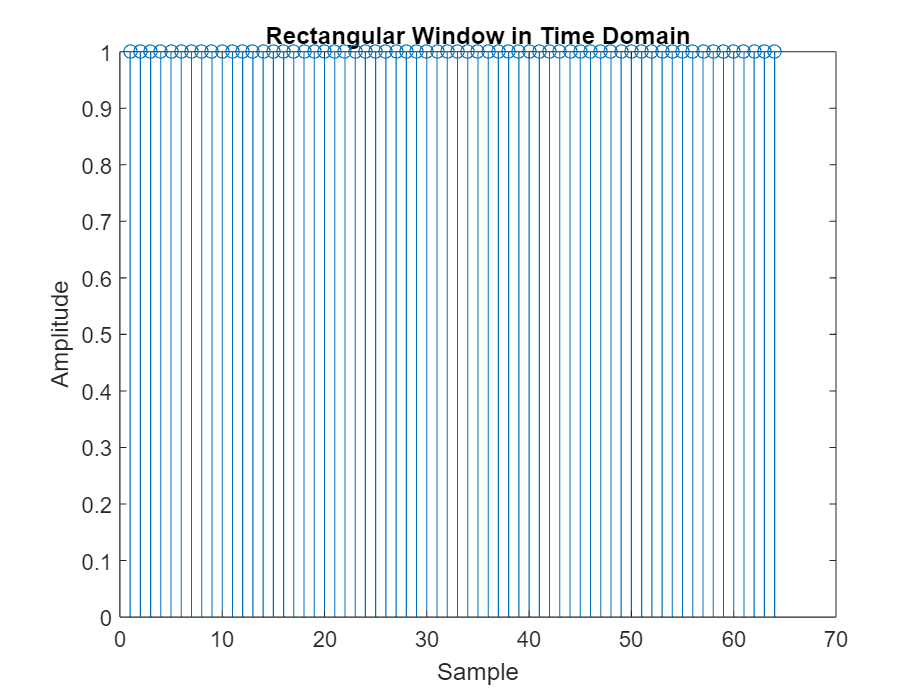

%problem 1: Design a high pass filter. We need to determine the impulse
%response given that it is causal and FIR
% note that we want a cutoff wc = pi/2 via the windowing method

%part a: use rectangular window
% Cutoff frequency
wc = pi/2;

% Window length (you can adjust this based on your requirements)
window_length = 64; %this will be adjusted bsed on the values to calculate with
frequencies = 0:pi/window_length:pi; % Frequency axis from 0 to pi

% Create the rectangular window
rectangular_window = rectwin(window_length);
% Plot the rectangular window in the frequency domain
window_spectrum = fft(rectangular_window);

stem(rectangular_window);
title('Rectangular Window in Time Domain');
xlabel('Sample');
ylabel('Amplitude');

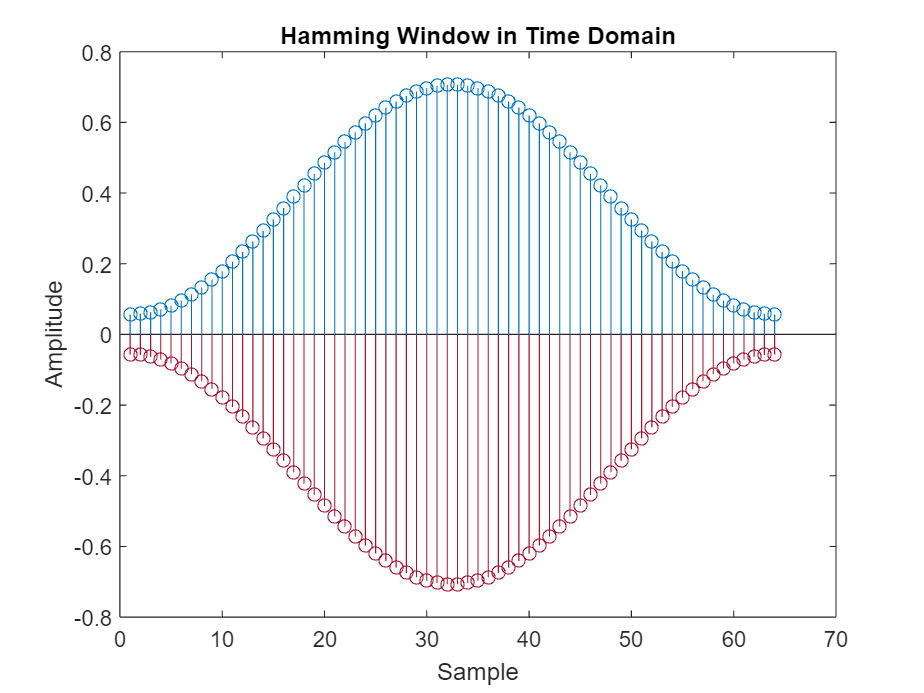



%part b: using hamming window
% Create the Hamming window
hamming_window = hamming(window_length);

% Normalize the Hamming window to have a cutoff frequency of wc
n = 0:window_length-1;
hamming_window = hamming_window .* cos((n - (window_length-1)/2) * wc);

% Plot the Hamming window in the frequency domain
window_spectrum = fft(hamming_window);

stem(hamming_window);
title('Hamming Window in Time Domain');
xlabel('Sample');
ylabel('Amplitude');



%part c: if a given fs = 1000hz, what would be the cutoff frequency in Hz
%and the frequency resolution?

% The cuttoff frequency wc can be determined considering the base equation wc = 2*pi*Fc 
% but since we know that wc is pi/2, we can adjust the form to calcuate setting the equation as follows:
% pi/2 = 2*pifc
% fc = (pi/2)/2*Pi
% fc = 1/4...

% Now, to determine frequency resolution, we can take the following formula into consideration:
% Fr = fs/N 
% we are not given an N in this case. Since I have been using the value 64 for windowing N, 
% I will use 64 for N again here.
% Fr = 1000/64;
% Fr = 15.625Hz 
% 

%part d: test filters in a and b on a design and plot the transform of the
%output.
%these are the values required to push through the filters built
A1 = 1;
f1 = 400;
duration = 1;
t = 0:1/f1:duration-1/f1;

% Generate the original signal
gsig = A1 * sin(2 * pi * f1 * t);

% Apply the rectangular window
rectangular_windowed_signal = gsig .* rectwin(length(t));

% Plot the original and windowed signals
plot(t, gsig);
title('Original Signal');
xlabel('Time (s)');
ylabel('Amplitude');

%plotting the rectangular signal
plot(t, rectangular_windowed_signal);
title('Rectangular Windowed Signal');

% Apply the Hamming window
hamming_windowed_signal = gsig .* hamming(length(t));


%plotting the hamming window response
plot(t, hamming_windowed_signal);
title('Hamming Windowed Signal');

%as can be seen by comparing these two signal results, due to the
%limitation of the two windowing styles as they only take a sampling value
%for parameters, they are not precise but, the hamming window displays a
%better result rather than a straight line.

%problem 2: design a band pass filter
%determine the impulse response of a causal, nonrecursive (FIR) filter to
%be used to process analog data sampled at fs = 1000hz.
%include the specifications where the passband is between 200 and 250hz,
%and frequency resolution is 20hz.

Fs = 1000;
Fr = 20;
start_frequency = 200;      % Start frequency in Hz
end_frequency = 250;        % End frequency in Hz

f = 0:1:Fs;

%now, to built the length of the signal
%and make sure it is 1 when we expect it to be
Hf = zeros(size(f));

% Set values in the passband to 1
for i = 1:length(f)
    if (start_frequency <= i * Fs / length(f)) && (i * Fs / length(f) <= end_frequency)
        Hf(i) = 1;
    end
end

%part a: sketch |H(f)|
% Plot the signal
stem(Hf);
title('Problem 1a: Sketch of |H(f)|');
xlabel('Frequency (Hz)');
ylabel('Amplitude');% Set values in the passband to 1

%Part b: graph |H(w)|
% Plot the spectrum |H(w)|

stem( abs(fft(Hf/(2*pi)))/length(Hf/(2*pi))*2);
title('Frequency Spectrum');
xlabel('Frequency (Hz)');
ylabel('Amplitude');
xlim([0, Fs/2]);

% Adjust the axis for better visibility
axis tight;

%part c
% Inverse Fourier Transform to get continuous-time impulse response h(t)
ht = ifft(ifftshift(Hf));

% Discretization to obtain discrete-time impulse response hn
Fs = 1000; % Sampling rate
Ts = 1 / Fs; % Sampling period
t_discrete = 0:Ts:(length(ht) - 1) * Ts;
hn = ht * Ts; % Discretization

% Apply rectangular window to hn
window_size = 32; % Adjust the window size as needed
rectangular_window = ones(1, window_size);
hw_n = hn(1:window_size) .* rectangular_window;

% Plot the results
figure;
subplot(2, 1, 1);
plot(t_discrete, hn);

title('Discrete-time Impulse Response h[n]');
xlabel('Time (s)');
ylabel('h[n]');

subplot(2, 1, 2);
stem(0:window_size-1, hw_n);

title('Impulse Response with Rectangular Window');
xlabel('Sample');
ylabel('h_w[n]');
%part d: h(n) using ham filtering
% Discretization to obtain discrete-time impulse response hn
Ts = 1 / Fs; % Sampling period
t_discrete = 0:Ts:(length(ht) - 1) * Ts;
hn2 = ht * Ts; % Discretization

% Apply Hamming window to hn
window_size = 32; % Adjust the window size as needed
hamming_window = hamming(window_size)';
hw_n = hn2(1:window_size) .* hamming_window;

% Plot the results
figure;
subplot(2, 1, 1);
plot(t_discrete, hn2);

title('Discrete-time Impulse Response h[n]');
xlabel('Time (s)');
ylabel('h[n]');

subplot(2, 1, 2);
stem(0:window_size-1, hw_n);

title('Impulse Response with Hamming Window');
xlabel('Sample');
ylabel('h_w[n]');
%part e: plot the frequency response (Hz) of the filters designed in c and
%d.
% Original impulse response h(t)
t_continuous = 0:0.001:(length(ht) - 1) * Ts; % Adjust the time resolution as needed
ht_continuous = sinc(t_continuous); % Example impulse response (replace with your actual impulse response)

% Discretization to obtain discrete-time impulse response hn
Fs = 1000; % Sampling rate
Ts = 1 / Fs; % Sampling period
t_discrete = 0:Ts:(length(ht) - 1) * Ts;
hn = ht * Ts; % Discretization

% Frequency response of the original impulse response
[frequencies, original_response] = freqz(ht, 1, 'whole', Fs);

% Apply rectangular window to hn
window_size = 32; % Adjust the window size as needed
rectangular_window = ones(1, window_size);
hw_n = hn(1:window_size) .* rectangular_window;

% Frequency response of the impulse response with rectangular window
[frequencies_rect, response_rect] = freqz(hw_n, 1, 'whole', Fs);

% Plot the results

plot(t_continuous, ht_continuous);
title('Continuous-time Impulse Response h(t)');
xlabel('Time (s)');
ylabel('h(t)');

plot(frequencies, abs(original_response));

title('Frequency Response of Original Impulse Response');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

plot(frequencies_rect, abs(response_rect));

title('Frequency Response of Impulse Response with Rectangular Window');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

% Apply Hamming window to hn
window_size = 32; % Adjust the window size as needed
hamming_window = hamming(window_size)';
hw_n = hn2(1:window_size) .* hamming_window;

% Frequency response of the impulse response with Hamming window
[frequencies_hamming, response_hamming] = freqz(hw_n, 1, 'whole', Fs);
frequencies_hz_hamming = frequencies_hamming * (Fs / (2 * pi)); % Convert to hertz

% Plot the results
figure;
subplot(2, 1, 1);
plot(frequencies_hz_hamming, abs(response_hamming));

title('Frequency Response of Impulse Response with Hamming Window');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

subplot(2, 1, 2);
stem(0:window_size-1, hw_n);

title('Impulse Response with Hamming Window');
xlabel('Sample');
ylabel('h_w[n]');



%Problem 3: Design a Low Pass Filter. Determine the impulse response of a
%causal, nonrecursive(FIR) filter with the following specifications. Use
%optimum equirriple frequency sampling method.
% Filter specifications
passband_freq = 1500;         % Passband frequency in Hz
transition_width = 500;       % Transition width in Hz
stopband_attenuation = 50;    % Stopband attenuation in decibels
Fs = 8000;                    % Sampling frequency in Hz

% Calculate the normalized frequencies
passband_edge = passband_freq / Fs;
transition_width_norm = transition_width / Fs;
stopband_edge = (passband_freq + transition_width) / Fs;

% Design the filter using firpm
filter_order = 50; % Adjust as needed
b = firpm(filter_order, [0, passband_edge, stopband_edge, 0.5], [1, 1, 0, 0], [1, 10^(-stopband_attenuation/20)], 'firpm');

% Impulse response
hn = b;

%part b: plot the frequency response H(w)
% Calculate the DFT of the impulse response
N = length(hn);  % Length of the impulse response
Hw = fft(hn, N);  % Discrete Fourier Transform

% Frequency axis in Hz
frequencies = 0:Fs/2:N/2+1;

% Plot the magnitude of the frequency response
figure;
plot(frequencies, abs(Hw(1:N/2 + 1)))

title('Frequency Response');
xlabel('Frequency (Hz)');
ylabel('|H(\omega)|');


%part c: compute the resultant stopband attenuation found
% Find the index corresponding to the stopband edge frequency
stopband_edge_index = round(stopband_edge * N / (Fs/2));

% Calculate the resultant stopband attenuation
stopband_amplitude = abs(Hw(stopband_edge_index + 1));
passband_amplitude = abs(Hw(2));  % Assuming 1st bin corresponds to DC, so passband is at index 2
resultant_stopband_attenuation = -20 * log10(stopband_amplitude / passband_amplitude);

% Display the resultant stopband attenuation
fprintf('Resultant Stopband Attenuation: %.2f dB\n', resultant_stopband_attenuation);

Resultant Stopband Attenuation: 17.75 dB


%Problem 4

%part a
% Discrete angular frequency range
w = -pi:1:pi;

% Digital differentiator prototype (continuous)
Hf = 1j * 2 * pi * w;

% Bilinear transformation to obtain the discrete-time digital differentiator
Hz = Hf ./ (1 - exp(-1j * w));

% Plot the amplitude
figure;
subplot(2, 1, 1);
plot(w, abs(Hz));
title('Amplitude of Hdw');
xlabel('Digital Frequency (\omega)');
ylabel('|Hdw(e^{j\omega})|');

% Plot the phase (angle)
subplot(2, 1, 2);
plot(w, angle(Hz));
title('Phase of Hdw');
xlabel('Digital Frequency (\omega)');
ylabel('Angle of Hdw(e^{j\omega})');
%part b
%determine the impulse response of the ideal digital differentiator

% Adjust Hz to match the desired impulse response h_dw[n]
hz_adjusted = Hz;
hz_adjusted(abs(w) < 1e-10) = 0; % Set Hz to 0 at DC to ensure h[0] = 0
%this next one should ensure that the values are
hz_adjusted(abs(w) > 1e-10) = hz_adjusted(abs(w) > 1e-10) .* (-1).^(1:sum(abs(w) > 1e-10)) ./ abs(w(abs(w) > 1e-10));

% Compute the inverse discrete Fourier transform (IDFT)
h_dw = ifft(hz_adjusted);

% Time axis
n = 0:length(h_dw)-1;

% Plot the impulse response
figure;
stem(n, real(h_dw));
title('Impulse Response of Adjusted Hdw');
xlabel('Sample');
ylabel('h_{dw}[n]');

%if you look at this from n = 1 and on, you can see that for some values
%the rule of hdn for absolute value of n results in ((-1)^n)/n although I
%feel my implementation may have squeued the results displayed above...

%part c
%below you will find the function created that should determine the
%expression of the coefficients of hrect(n) with length N = 2P+1

% function h = rectangularFilter(P)
%     N = 2 * P + 1;  % Filter length
%     n = -(P):P;     % Time indices
% 
%     % Define the impulse response of the filter
%     h_rect = double(abs(n) <= P);
% 
%     % Apply the rectangular window
%     w_rect = double(abs(n) <= P);
% 
%     % Obtain the coefficients h_rect[n]
%     h = h_rect .* w_rect;
% end


%Problem 5
%part a
% Define the frequency range
w1 = pi/5;
w2 = pi/2;

% Filter length
N = 1000;

% Compute the impulse response coefficients
h_dbw = digitalDifferentiator(w1, w2, N);

% Frequency axis
%omega = 0:pi;

% Plot the magnitude of the frequency response
figure;
subplot(2, 1, 1);
plot(abs(fft(h_dbw)));
title('Magnitude of Hdbw');
xlabel('Digital Frequency (\omega)');
ylabel('|Hdbw(e^{j\omega})|');

% Plot the phase (angle) of the frequency response
subplot(2, 1, 2);
plot(angle(fft(h_dbw)));
title('Phase of Hdbw');
xlabel('Digital Frequency (\omega)');
ylabel('Angle of Hdbw(e^{j\omega})');


%part b
%please refer back to the function built in problem 4 part c
%

%part c
%using the design for bandpass filter I will find the frequency response
%for hbp(n)
% Define the frequency range and stopband attenuation
w1 = pi/5;
w2 = pi/2;
P = 50;
As = 40;  % Stopband attenuation in dB

% Compute the impulse response coefficients
h_bp = bandpassFilter(w1, w2, P, As);

% Frequency axis
omega = linspace(0, pi, length(h_bp));

% Plot the magnitude of the frequency response
figure;
subplot(2, 1, 1);
plot(omega, abs(fft(h_bp)));
title('Magnitude of Hbp');
xlabel('Digital Frequency (\omega)');
ylabel('|Hbp(e^{j\omega})|');

% Plot the phase (angle) of the frequency response
subplot(2, 1, 2);
plot(omega, angle(fft(h_bp)));
title('Phase of Hbp');
xlabel('Digital Frequency (\omega)');
ylabel('Angle of Hbp(e^{j\omega})');

%part d: doing the same as part c, using optimal equiripple frequency
%sampling.

% Define the frequency range and stopband attenuation
w1 = 5/pi;
w2 = pi/2;
As = 40;  % Stopband attenuation in dB

% Choose the filter length
N = 251;  % Adjust as needed

% Define the frequency bands and corresponding amplitudes
freq_bands = [0, w1, w2, pi];
ampl_db = [0, 0, -As, -As];

% Design the bandpass filter using optimal equiripple method
%to do this I should be able to use firpm but there are compilation issues
%I'm not sure how to diagnose...
h_bp = firpm(N-1, freq_bands./pi, 10.^(ampl_db/20), {1, 1});

Error using firpminit
Frequencies must be non-decreasing.

Error in firpm (line 139)
[nfilt,ff,grid,des,wt,ftype,sign_val,hilbert,neg] = firpminit(order, ff, aa, varargin{:});


% Normalize by dividing by the sum to make it a true bandpass filter
h_bp = h_bp / sum(h_bp);

% Frequency axis
omega = linspace(0, pi, length(h_bp));

% Plot the magnitude and phase of the frequency response
figure;
subplot(2, 1, 1);
plot(omega, abs(fft(h_bp)));
title('Magnitude of Hbp (Optimal Equiripple)');
xlabel('Digital Frequency (\omega)');
ylabel('|Hbp(e^{j\omega})|');

subplot(2, 1, 2);
plot(omega, angle(fft(h_bp)));
title('Phase of Hbp (Optimal Equiripple)');
xlabel('Digital Frequency (\omega)');
ylabel('Angle of Hbp(e^{j\omega})');
